# Big Data Workflow using Datastore and Tall Arrays

## Initialize

clear all
clc

## Generate some Dig Data

%generate a set of big data
x = linspace(1,1e3,1e6)';
y = sin(x);
y2 = (sin(x)+randn(length(x),1));

%save in the workspace
t1 = table(x,y,y2);
location = pwd;
writetable(t1,'testdata_t1')

%generate another set of big data
x = linspace(1,1e3,1e6)';
y = sin(x);
y2 = (sin(x)+randn(length(x),1));

%save in the workspace
t2 = table(x,y,y2);
location = pwd;
writetable(t2,'testdata_t2')

%clear the workspace, use the big data in the folder directory
clear all

## Preprocessing

%datastore reads the directories metadata without loading into the workspace

%find all .txt files
ds = datastore('*.txt');
ds.Files

ans = 2×1 cell array
    {'C:\Users\fm782d\Documents\MATLAB\Examples\big data\testdata_t1.txt'}
    {'C:\Users\fm782d\Documents\MATLAB\Examples\big data\testdata_t2.txt'}


%how many files were found. use this for looping.
numFiles = length(ds.Files)

numFiles = 2

%create filename holding array
filenames = cell(1,numFiles)'

filenames = 2×1 cell array
    {0×0 double}
    {0×0 double}


## Importing Tall Arrays, and Saving

%loop thru and create tall arrays using metadata approach
for k = 1:numFiles
    
    %from fileparts, find the .txt file name
    [filepath,filename,ext]=fileparts(ds.Files{k});
    
    %as a form of datastore, use tabularTextDatastore to read metadata
    tableBase = tabularTextDatastore(ds.Files{k});
    
    %create a tall array with a common 'tableBase' base name in workspace
    tableBase = tall(tableBase);
    
    %save 'tableBase' as the filename (original .txt file name)
    save(filename,'tableBase');
    
    %save the filename in the filename array for looping later...
    filenames{k} = filename;
    
end

Starting parallel pool (parpool) using the 'local' profile ...
connected to 4 workers.


%display the filenames to confirm and use for later
filenames

filenames = 2×1 cell array
    {'testdata_t1'}
    {'testdata_t2'}


## Working with the Data

%Before
load(string(filenames{1}) + ".mat")  
tableBase


tableBase =

  M×3 tall table

      x         y          y2   
    _____    _______    ________

        1    0.84147      1.3791
    1.001    0.84201      2.6759
    1.002    0.84255     -1.4163
    1.003    0.84309      1.7053
    1.004    0.84362      1.1624
    1.005    0.84416    -0.46353
    1.006    0.84469      0.4111
    1.007    0.84523      1.1879
      :         :          :
      :         :          :



load(string(filenames{2}) + ".mat") 
tableBase


tableBase =

  M×3 tall table

      x         y          y2   
    _____    _______    ________

        1    0.84147     0.74018
    1.001    0.84201      1.7354
    1.002    0.84255      2.0126
    1.003    0.84309      1.7354
    1.004    0.84362      1.0516
    1.005    0.84416      -0.184
    1.006    0.84469     0.85494
    1.007    0.84523    -0.16448
      :         :          :
      :         :          :



%Data Manipulation
for k = 1:numFiles
    load(string(filenames{k}) + ".mat")    
    tableBase.delta = tableBase.y - tableBase.y2
    save(filenames{k},'tableBase')
end


tableBase =

  M×4 tall table

      x         y          y2        delta  
    _____    _______    ________    ________

        1    0.84147      1.3791    -0.53767
    1.001    0.84201      2.6759     -1.8339
    1.002    0.84255     -1.4163      2.2588
    1.003    0.84309      1.7053    -0.86217
    1.004    0.84362      1.1624    -0.31877
    1.005    0.84416    -0.46353      1.3077
    1.006    0.84469      0.4111     0.43359
    1.007    0.84523      1.1879    -0.34262
      :         :          :           :
      :         :          :           :


tableBase =

  M×4 tall table

      x

%After
load(string(filenames{1}) + ".mat")  
tableBase


tableBase =

  M×4 tall table

      x         y          y2        delta  
    _____    _______    ________    ________

        1    0.84147      1.3791    -0.53767
    1.001    0.84201      2.6759     -1.8339
    1.002    0.84255     -1.4163      2.2588
    1.003    0.84309      1.7053    -0.86217
    1.004    0.84362      1.1624    -0.31877
    1.005    0.84416    -0.46353      1.3077
    1.006    0.84469      0.4111     0.43359
    1.007    0.84523      1.1879    -0.34262
      :         :          :           :
      :         :          :           :




load(string(filenames{2}) + ".mat") 
tableBase


tableBase =

  M×4 tall table

      x         y          y2         delta  
    _____    _______    ________    _________

        1    0.84147     0.74018      0.10129
    1.001    0.84201      1.7354     -0.89334
    1.002    0.84255      2.0126      -1.1701
    1.003    0.84309      1.7354     -0.89232
    1.004    0.84362      1.0516     -0.20798
    1.005    0.84416      -0.184       1.0282
    1.006    0.84469     0.85494    -0.010246
    1.007    0.84523    -0.16448       1.0097
      :         :          :            :
      :         :          :            :



## Visualization Functions

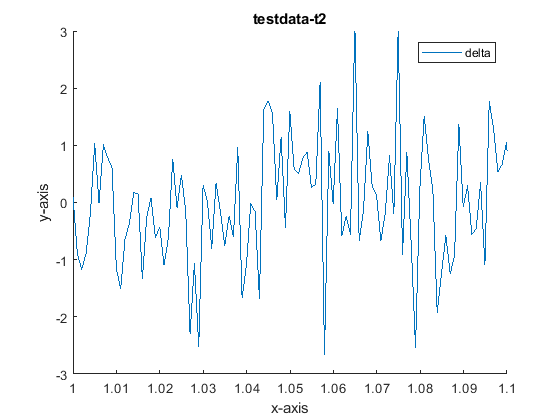

%Loop thru filenames to create plots for each case
for k = 1:numFiles   
    
    %load .mat file from directory to workspace
    load(string(filenames{k}) + ".mat")  
    
    %make a folder with the filename
    mkdir("Figures for " + string(filenames{k}));
    
    %switch into that folder
    cd("Figures for " + string(filenames{k}));
    
    %create a bunch of plots in that folder
    plot(tableBase.x,tableBase.y2); hold on;
    plot(tableBase.x,tableBase.y,'LineWidth',2); hold off;
    title(replace(filenames{k},'_','-'))
    legend('y','y2')
    xlabel('x-axis')
    ylabel('y-axis')
    grid on; grid minor
    xlim([1 10])
    ylim([-4 4])
    
    %save plot as a .png picture file
    print('Clip','-dpng')
   
    plot(tableBase.x,tableBase.delta); hold off;
    title(replace(filenames{k},'_','-'))
    legend('delta')
    xlabel('x-axis')
    ylabel('y-axis')
    xlim([1 1.1])
    ylim([-3 3])
    
    %save plot as a .png picture file
    print('Delta','-dpng')

    %switch back up a folder level to the main folder
    cd ..

end

%compare plots - plots to compare deltas from two test data cases
for k = 1:numFiles
    
    %load .mat files for the given filename
    load(string(filenames{k}) + ".mat")    
    plot(tableBase.x,tableBase.delta); hold on;
    
    title('Delta Compare')
    legend('testdata-t1 delta','testdata-t2 delta')
    xlabel('x-axis')
    ylabel('y-axis')
    xlim([1 1.1])
    ylim([-3 3])
    
    %save a comparison plot in each subfolder
    cd("Figures for " + string(filenames{k}));
    
    %save plot as a .png
    print('Delta Comparison','-dpng')
    
    %switch back into the main folder
    cd .. 
    
end

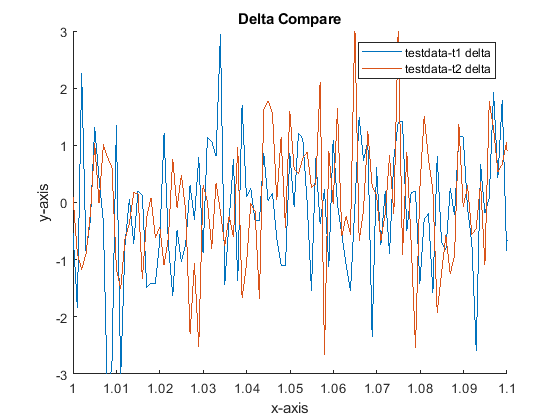

hold off

## Appendix - Additional Live Script Plots for Testing

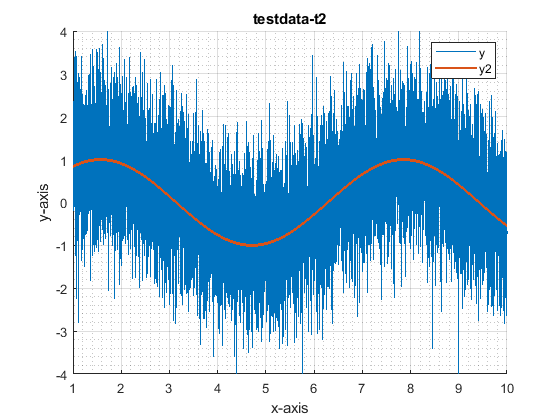

%plots for the live script for inspection & testing
plot(tableBase.x,tableBase.y2); hold on;
plot(tableBase.x,tableBase.y,'LineWidth',2); hold off;
title(replace(filenames{k},'_','-'))
legend('y','y2')
xlabel('x-axis')
ylabel('y-axis')
grid on; grid minor
xlim([1 10])
ylim([-4 4])


plot(tableBase.x,tableBase.delta); hold off;
title(replace(filenames{k},'_','-'))
legend('delta')
xlabel('x-axis')
ylabel('y-axis')
xlim([1 1.1])
ylim([-3 3])